%% 无人机阵列雷达仿真系统
% 作者：jinyong
% 最后修改时间：2025-3-11
% 版本：v1.0

%% Ⅰ. 系统参数配置
clear; clc; close all;

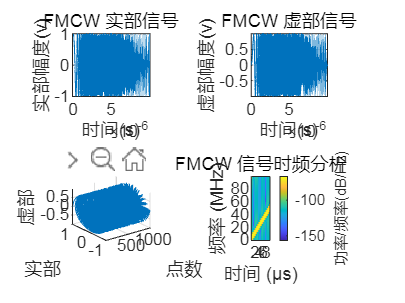


% ================== 雷达系统参数 ==================
fc = 300e6;            % 中心频率300MHz（米波雷达典型值）T
c = physconst('LightSpeed');
lambda = c/fc;         % 波长计算

% FMCW波形参数
bw = 50e6;             % 调频带宽50MHz（折中考虑分辨率与实现难度）
T = 10e-6;    % 扫频时间10us
B = bw;         % 扫频带宽
fs=2*bw;

waveform = phased.FMCWWaveform('SweepTime',T,...
                              'SweepBandwidth',B,...
                              'SampleRate',fs);
sig = waveform();
% sp.spec(sig,fs,1000);
fenxi(sig,fs,T);

% subplot(221);
% plot(0:1/fs:T-1/fs,real(sig));
% xlabel('时间(s)'); ylabel('实部幅度(v)');
% title('FMCW 实部信号'); axis tight;grid on
% subplot(222);
% plot(0:1/fs:T-1/fs,imag(sig));
% xlabel('时间(s)'); ylabel('虚部幅度(v)');
% title('FMCW 虚部信号'); axis tight;grid on
% subplot(223)
% sp.p3(sig);
% grid on;axis tight;
% subplot(224);
% spectrogram(sig,32,16,32,fs,'yaxis');
% title('FMCW 信号时频分析');


% ================== 阵列参数 ==================
numElements = 6;       % 阵列尺寸
elementSpacing = lambda/2;  % 阵元间距半波长

% array = phased.ULA('NumElements',numElements,...
%                   'ElementSpacing',elementSpacing,...
%                   'ArrayAxis','y'); % y轴排布
% getElementPosition(array,1)
% getElementPosition(array)

elementPos=zeros(3,numElements);
elementPos(2,:)=elementSpacing*((1:size(elementPos, 2))-1);

array = phased.ConformalArray('ElementPosition', elementPos);
positions = getElementPosition(array);
disp(positions);

         0         0         0         0         0         0
         0    0.4997    0.9993    1.4990    1.9986    2.4983
         0         0         0         0         0         0



% ================== 平台运动参数 ==================
% platformHeight = 500;  % 飞行高度500m
% array_ini_pos=[0; 0; 0];
% r_t_Antenna =phased.Platform('InitialPosition',array_ini_pos, ...
%                                     'Velocity',velocity);

velocity = [0;elementSpacing;0];   % 平台运动速度(m/s)，沿y轴方向




% ================== 发射机配置 ==================
txPower = 1000;          % 发射功率1000W
transmitter = phased.Transmitter('PeakPower', txPower,...
                                'Gain', 20,...
                                'InUseOutputPort', true);

% ================== 接收机配置 ==================
noiseFigure = 0.0;      % 接收机噪声系数2dB
rxGain = 30;            % 接收增益30dB
receiver = phased.ReceiverPreamp('Gain', rxGain,...
                                'NoiseFigure', noiseFigure,...
                                'SampleRate', waveform.SampleRate);
    
% ================== 发射天线配置 ==================
radiator = phased.Radiator('Sensor', array,...
                              'OperatingFrequency', fc,...
                              'PropagationSpeed', c);
% radiated_sig = radiator(tx_sig, [0;0]); % 波束指向角度
% ================== 接收天线配置 ==================
collector = phased.Collector('Sensor', array,...
                                'OperatingFrequency', fc,...
                                'PropagationSpeed', c);
% collected_sig = collector(received_sig, [0;0]); % 接收方向

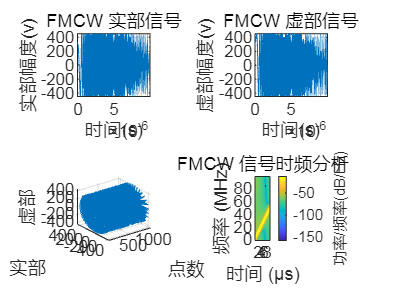



% 配置传播环境（自由空间模型）
env = phased.FreeSpace('PropagationSpeed',c,...
                      'OperatingFrequency',fc);

%% Ⅲ. 目标场景设置
% 生成多个随机目标参数
numTargets = 1;  % 目标数量
targetRange = linspace(5000,10000,numTargets);  % 目标距离
% targetAzimuth = rand(1,numTargets)*60-30;       % 方位角-30°~30°
targetAzimuth=linspace(30,30,numTargets);
targetSpeed = rand(1,numTargets)*50 -25;        % 速度-25~25m/s
targetRCS = rand(1,numTargets)*9.9+0.1;  % RCS 0.1~10 m²

% 创建目标平台数组
targets = repmat(struct(...
    'Platform', phased.Platform,...
    'Signature', phased.RadarTarget), 1, numTargets);

for k = 1:numTargets
    % 设置目标初始位置（极坐标转笛卡尔）
    [x,y] = pol2cart(deg2rad(targetAzimuth(k)),targetRange(k));
    targets(k).Platform.InitialPosition = [x; y; 0];
    targets(k).Platform.Velocity = [0;targetSpeed(k);0]; % 横向运动
    targets(k).Signature.MeanRCS = targetRCS(k);
end

%% Ⅳ. 信号生成与处理
% 仿真时间参数设置
numPulses = 64;       % 脉冲积累数
fs = waveform.SampleRate;
rx_signals = complex(zeros(numElements,numPulses,round(waveform.SampleRate*T)));

% 主仿真循环
for pulseIdx = 1:numPulses

    % 发射信号生成
    tx_sig = waveform();
    % fenxi(tx_sig,fs,T);

    % 多目标回波接收
    % for elemIdx = 1:numElements
        % 更新阵元位置
        a_pos=getElementPosition(array);
        elemPos = (a_pos(:,3)+a_pos(:,4))/2+velocity*pulseIdx;
        % [rta_pos,rta_vel]=r_t_Antenna(pulseIdx);
        % elemPos = getElementPosition(array,elemIdx) + rta_pos;
        % 遍历所有目标
        for tgtIdx = 1:numTargets
            % 计算目标当前状态
            [tgtPos,tgtVel] = targets(tgtIdx).Platform(pulseIdx);
            
            % 更新目标角度和位置
            [~,txang] = rangeangle(tgtPos,elemPos);
            [~,tgang] = rangeangle(elemPos,tgtPos);
            
            % 通过发射机发射脉冲
            [sig,txstatus] = transmitter(tx_sig);

            % 通过发射天线（按照特定方向就是上面的目标角度）
            sig = radiator(sig,txang);

            % % 通过自由空间
            prop_sig = env(sig,elemPos,tgtPos,velocity,tgtVel);
            fenxi(reshape(sig(:,1),1000,1),fs,T);

            % 目标反射信号
            % refl_sig = targets(tgtIdx).Signature(prop_sig,txang);
            refl_sig = targets(tgtIdx).Signature(sig);
            fenxi(reshape(refl_sig(:,1),1000,1),fs,T);

            % 
            % % 回波信号继续传回去
            refl_sig = env(refl_sig,tgtPos,elemPos,tgtVel,velocity);
            fenxi(reshape(refl_sig(:,1),1000,1),fs,T);
            % 

            % 接收天线接收
            refl_sig = collector(refl_sig,txang);
            
            fenxi(reshape(refl_sig(:,1),1000,1),fs,T);

            rx_signals(:, pulseIdx, :) = rx_signals(:, pulseIdx, :)+reshape(receiver(refl_sig).',6,1,1000);
            % [~,rxang] = rangeangle(elemPos,tgtPos)

        end
    % end
end

% rx_ex=reshape(rx_signals(1,1,:),1000,1) ;
fenxi(reshape(rx_signals(1,1,:),1000,1),fs,T);



rx_ex=reshape(rx_signals(:,1,:),6,1000);
zeta=[0,1,2,3,4,5];
a_zeta=exp(-1i*2*pi*zeta*elementSpacing*sin(pi/6)/lambda);
rx_ex=a_zeta*rx_ex;

size(0:1/fs:T-1/fs)
size(rx_ex)

fenxi(rx_ex.',fs,T);




% subplot(221);
% plot(0:1/fs:T-1/fs,real(rx_ex));
% xlabel('时间(s)'); ylabel('实部幅度(v)');
% title('FMCW 实部信号'); axis tight;grid on
% subplot(222);
% plot(0:1/fs:T-1/fs,imag(rx_ex));
% xlabel('时间(s)'); ylabel('虚部幅度(v)');
% title('FMCW 虚部信号'); axis tight;grid on
% subplot(223)
% sp.p3(rx_ex.');
% grid on;axis tight;
% subplot(224);
% spectrogram(rx_ex,32,16,32,fs,'yaxis');
% title('FMCW 信号时频分析');

% %% Ⅴ. 数据保存与可视化
% % 保存接收信号（供后续处理）
% save('radar_data.mat','rx_signals','fs','fc','bw','numElements','elementSpacing');
% 
% % 显示阵列配置
% viewArray(array,'Title','无人机阵列配置');
% 
% % 显示目标分布
% figure;
% polarscatter(deg2rad(targetAzimuth),targetRange,[],targetRCS,'filled');
% title('目标空间分布'); colorbar; 

% % 创建初始阵列（4个阵元沿x轴分布）
% elementPos = [0, 1, 2, 3; 0, 0, 0, 0; 0, 0, 0, 0];
% array = phased.ConformalArray('ElementPosition', elementPos);
% positions = getElementPosition(array);
% disp(positions);
% % 动态修改为圆形布局
% theta = linspace(0, 2*pi, 4); % 4个角度
% new_x = cos(theta); 
% new_y = sin(theta);
% array.ElementPosition = [new_x; new_y; zeros(1,4)]; % 3×4矩阵
% positions = getElementPosition(array);
% disp(positions);